## Robustness analysis of a spark ignition engine - Report

###                                                             - Akash Sharma, Tushar Bhatt

clear all
clc
close all

## Gain and Delta ranges

K1min = 2.1608;
K1max = 3.4329;
K2min = 0.1027;
K2max = 0.1627;
K3min = 0.0357;
K3max = 0.1139;
K4min = 0.2539;
K4max = 0.5607;
K5min = 0.17993;
K5max = 2.1999;
K6min = 1.8078;
K6max = 3.8429;
K7min = 1.8201;
K7max = 2.0283;
K8min = 0.1;
K8max = 1;

Based on these bound values of gain, the corresponding bounds of deltas are as follows.

d1min = K1min;
d1max = K1max;
d2min = -K2max;
d2max = -K2min;
d3min = -K3max;
d3max = -K3min;
d4min = K4min;
d4max = K4max;
d5min = K5min - K7min;
d5max = K5max - K7max;
d6min = K6min;
d6max = K6max;
d7min = K8min;
d7max = K8max;

## GSS Objects Creation

% The empty bracket input argument corresponds to providing the nominal
% value as the mean of the uncertainty.

d1 = gss('d1',[],[d1min d1max]);
d2 = gss('d2',[],[d2min d2max]);
d3 = gss('d3',[],[d3min d3max]);
d4 = gss('d4',[],[d4min d4max]);
d5 = gss('d5',[],[d5min d5max]);
d6 = gss('d6',[],[d6min d6max]);
d7 = gss('d7',[],[d7min d7max]);

% State Space Model

A = [d5*d7 d4*d7 ; d3 d2];
B = [0 d6*d7 ; d1 0];
C = eye(2);
D = zeros(2);

sys_1 = ss(A,B,C,D); % Open Loop parametric model

The state space model obtained contains 2 states, 11 inputs and 11 outputs. The range of variation (Bounds) and the nominal values (NomValue) of the delta variables are shown in the table above.

## Closed Loop State Space

G = [0.0081 0.0872 0.1586 -0.1202 ; 0.0187 0.1826 0.0848 -0.0224]; % Controller Gain matrix

[CA,CB,CC,CD] = linmod('Controller_Block');

Found algebraic loop containing: 
Controller_Block/Gain1
Controller_Block/Gain
Controller_Block/Gain
Controller_Block/Transfer Fcn
Controller_Block/Sum2 (algebraic variable)


controller = ss(CA,CB,CC,CD) % State Space controller with 2 states, 2 inputs and 2 outputs

controller =
 
  A = 
            x1       x2
   x1        0        0
   x2   0.0187  -0.0276
 
  B = 
           u1      u2
   x1       1       0
   x2  0.1826  0.0848
 
  C = 
            x1       x2
   y1   0.0081   0.1202
   y2   0.0187  -0.0276
 
  D = 
           u1      u2
   y1  0.0872  0.1586
   y2  0.1826  0.0848
 
Continuous-time state-space model.



sys_CL1 = feedback(controller*sys_1,eye(2));

The state space model $M\left(s\right)$ has **4 states, 11 inputs and 11 outputs.**

The values of q represent the number of times each delta value appears in the state space representation. Therefore, their values are given by the sizes of the respective Delta blocks.

sys_CL1.D(1).Size

ans =      1     1


sys_CL1.D(2).Size

ans =      1     1


sys_CL1.D(3).Size

ans =      1     1


sys_CL1.D(4).Size

ans =      1     1


sys_CL1.D(5).Size

ans =      1     1


sys_CL1.D(6).Size

ans =      1     1


sys_CL1.D(7).Size

ans =      3     3


We can see that $q_1 \ldotp \ldotp \ldotp q_6 =1$ while $q_7 =3$. Therefore, $\delta_7$ appears 3 times in the equations which can be seen in the state space representation.

## Stability Analysis

The **eval** function evaluates the system at the given gain values of each of the points A,B,C.

% Point A
sys_A = eval(sys_CL1,{'d1','d2','d3','d4','d5','d6','d7'},{2.1608,-0.1027,-0.0357,0.5607,2.1999-2.0283,3.8429,1});
eig(sys_A) % All stable

ans =   -0.3622 + 0.1989i
  -0.3622 - 0.1989i
  -0.1827 + 0.0000i
  -0.0960 + 0.0000i


% Point B
sys_B = eval(sys_CL1,{'d1','d2','d3','d4','d5','d6','d7'},{3.4329,-0.1627,-0.1139,0.2539,1.7993-1.8201,1.8078,1});
eig(sys_B) % All stable

ans =    -0.5470
   -0.3069
   -0.1403
   -0.0914


% Point C
sys_C = eval(sys_CL1,{'d1','d2','d3','d4','d5','d6','d7'},{2.1608,-0.1027,-0.0357,0.5607,1.7993-1.8201,3.8429,0.1});
eig(sys_C) % All stable

ans =   -0.0380 + 0.0848i
  -0.0380 - 0.0848i
  -0.0919 + 0.0000i
  -0.3773 + 0.0000i


After checking the eigenvalues of the function, we can see that all of them lie of the left-half plane at all three operating points. Therefore, the system is closed-loop stable at all points.

[sys_d,samples] = dbsample(sys_CL1,1000,{'d1','d2','d3','d4','d5','d6','d7'});

The for loop below check the stability of the gss object of each sample and detects the unstable ones. The samples are generated randomly.

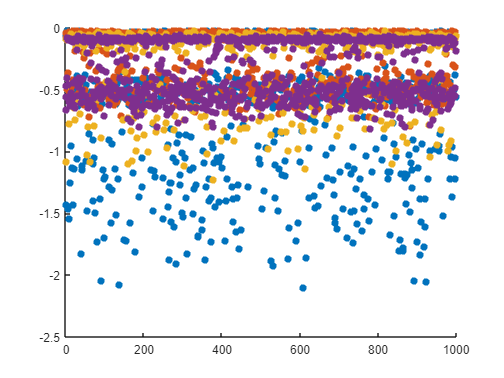

eigen_values = [];
unstable_deltas = [];
counter = 0;
for i=1:1000
    eigen_values = [eigen_values eig(sys_d{1,i}(1,1).A)];
    if ~ isstable(sys_d{1,i})
        unstable_deltas = [unstable_deltas ; samples(i,:)];
        counter = counter + 1; % Number of unstable samples
    end
end

sample_count = linspace(1,1000,1000);
scatter(sample_count,eigen_values,'filled') % Scatter plot of all the eigen-values

counter

counter = 0

In this case, all 1000 samples were found to be stable. We can see in the scatter plot that all eigen values lie below 0.

## Mu-Analysis

optub.lmi=1;optub.tol=0;
ubnd1=muub(sys_CL1([],[]),[],optub); % Exogenous inputs and outputs (D,A,N,P) are removed when we index the parametric model with empty brackets
[lbnd1,wc,pert,iodesc]=mulb(sys_CL1([],[]));

disp(['Upper Bound: ',num2str(ubnd1)])

Upper Bound: 1.0802


disp(['Lower Bound: ',num2str(lbnd1)])

Lower Bound: 0.8646


The upper bound of **µ** gives the condition for guaranteed stability of the system whereas the lower bound represents that there is at least one unstable value. However, it cannot be said if the system is stable /unstable beyond this threshold. Since the upper bound has a value greater than 1, the controller does not guarantee closed loop stability. The largest value for which the system is stable is $K_r =\frac{1}{\mu_{\mathrm{upper}} }=0\ldotp 925$. There was no unstable configuration found.

### Comparison between the 2 methods

The stability analysis in 2.2 used 1000 random samples of δ, but this method is considered conservative and may not consider the most critical cases. On the other hand, the μ-analysis in 2.3 evaluates all possible combinations of parameters to thoroughly examine the stability of the controller, particularly near instability limits, making it a more accurate approach. In our study, the sampling method in 2.2 was random. Moreover, the obtained upper bound of $\mu$ is only slightly above 1. Therefore, it was very likely that we would not find an unstable configuration. 

## Adjustment of the Combustion Chamber

K5min = 1.7993;
K5max = 2.0183;
K6min = 2.0247;
K6max = 4.4962;

d5min = K5min - K7min;
d5max = K5max - K7max;
d6min = K6min;
d6max = K6max;

d5 = gss('d5',[],[d5min d5max]);
d6 = gss('d6',[],[d6min d6max]);

A = [d5*d7 d4*d7 ; d3 d2];
B = [0 d6*d7 ; d1 0];
C = eye(2);
D = zeros(2);

sys_2 = ss(A,B,C,D); % New open loop parametric model with adjusted gains
sys_CL2 = feedback(controller*sys_2,eye(2)); % New closed loop parametric model

optub.lmi=1;optub.tol=0;
ubnd2=muub(sys_CL2([],[]),[],optub);
[lbnd2,wc,pert,iodesc]=mulb(sys_CL2([],[]));

disp(['Upper Bound: ',num2str(ubnd2)])

Upper Bound: 1.0021


disp(['Lower Bound: ',num2str(lbnd2)])

Lower Bound: 0.81818


We see that there is a marked improvement in both the bounds. The upper bound is much nearer to 1 even though it is still above it. This means that the system is stable for almost all values of **K** in the parametric domain. The largest value for which the system is stable is $K_r =\frac{1}{\mu_{\mathrm{upper}} }=0\ldotp 997$.

## Branch-and-Bound Algorithm

A branch and bound method is applied to reduce the gap between the upper and lower bounds of µ. An ϵ = 0.05 is chosen to minimize the bounds using the code below

optbb.maxgap=0.05;
[mubnds,wc,pert,iodesc]=mubb(sys_CL2([],[]),[],optbb);
disp(['Upper and Lower Bounds: ',num2str(mubnds)])

Upper and Lower Bounds: 0.81818     0.85909


The results are much better than before. While the lower bound remains the same, the upper bound decreases to below 1 which means that now the controller guarantees closed loop stability in the parametric domain **K**. $K_r =\frac{1}{\mu_{\mathrm{upper}} }=1\ldotp 164$.

## By Reducing the size of Delta

We can see that $\delta_7$ appears 3 times in the same equation of the state space representation. This was confirmed earlier by checking the value of $q_7$ being 3. Hence, we can say that it could be further factorized and its not minimal.

Generally, the compiler factorizes on its own however it does so by checking the leftmost values of the expression. Therefore, simply switching the values and keeping $\delta_7$ on the left in the state space representation, we can bypass this and achieve the minimal form. The rectification has been done below.

A = [d7*d5 d7*d4 ; d3 d2];
B = [0 d7*d6 ; d1 0];

sys_min = ss(A,B,C,D); % Minimal Open Loop parametric model
sys_CLmin = feedback(controller*sys_min,eye(2)); % Minimal Closed Loop parametric model

We can confirm the representation being minimal by rechecking the value of $q_7$ which is now 1.

sys_CLmin.D(7).Size

ans =      1     1


## $\mu$ Analysis of the minimal closed-loop parametric model

optub.lmi=1;optub.tol=0;
ubndmin=muub(sys_CLmin([],[]),[],optub);
[lbndmin,wc,pert,iodesc]=mulb(sys_CLmin([],[]));

disp(['Upper Bound: ',num2str(ubndmin)])

Upper Bound: 0.82682


disp(['Lower Bound: ',num2str(lbndmin)])

Lower Bound: 0.81818


After conducting the $\mu$ analysis with the minimal system the bound gap further decreases. The lower bound remains the same while the upper bound further drops to 0.8268. The corresponding largest gain is $K_r =\frac{1}{\mu_{\mathrm{upper}} }=1\ldotp 209$.

In μ analysis, factoring the system into its minimal form can reduce the value of μ because it eliminates any unnecessary elements that might contribute to instability. By reducing the complexity of the system, it becomes easier to identify the sources of instability and make the necessary adjustments to improve stability.